## INSTANCE ANALYSIS 

In this script we will analyze the results and 240 instances used in IS_Exp6 

 **CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities
addpath(genpath('Experiments/Feasibility/3. Instance Set'))
addpath(genpath('Solvers'))

**LOADING FILES**

%Loading set of instances
load('instances_adv1_adv2_comb.mat')

%Loading heuristics
load('LPT.mat')
load('SPT.mat')
load('MPA.mat')
load('LPA.mat')
%load('LPT_multi.mat')
%load('SPT_multi.mat')
load('MPA_multi.mat')
load('LPA_multi.mat')

%Loading HHs 
load('FM_HH1_multi.mat')
load('FM_HH2_multi.mat')
load('FM_HH3_multi.mat')

%Loading SHH1-SHH5
load("FM_SHH1.mat")
load("FM_SHH2.mat")
load("FM_SHH3.mat")
load("FM_SHH4.mat")
load("FM_SHH5.mat")

%Loading CHH1
load("FM_CHH1.mat")

%Loading randSHH and randCHH 
load('IS_Exp6_randSHH.mat') 
load('IS_Exp6_randCHH.mat')

%Loading solved instances
load('solvedInstances_IS_Exp6_randCHH_comb_makespans.mat')
load('solvedInstances_IS_Exp6_randSHH_comb_makespans.mat')

%Loading results from IS6
load('InstanceSet_Exp6_results.mat')

%Loading instances_comb optimum makespans variables
load('Instances_Comb_Optimums.mat')

**FIRST LET'S COMPARE THE RESULTS FROM IS_EXP6 AND THE OPTIMAL VALUES OF THE INSTANCES **

**First  we are going to obtain the means and mins of the 100 repetitions of each SHH and CHH for each instance.**

***This metrics are not that useful because does not feedback the performance of the random models; we can avoid running this section unless we cant to see the distribution of instances.***

SHH_means_1rule_byInstance=nan(240,31);
CHH_means_1rule_byInstance=nan(240,31);
SHH_mins_1rule_byInstance=nan(240,31);
CHH_mins_1rule_byInstance=nan(240,31);
for x=1:31
    SHH_means_1rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,1),2);
    CHH_means_1rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,1),2);
    SHH_mins_1rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,1)')';
    CHH_mins_1rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,1)')';
end

SHH_means_2rule_byInstance=nan(240,31);
CHH_means_2rule_byInstance=nan(240,31);
SHH_mins_2rule_byInstance=nan(240,31);
CHH_mins_2rule_byInstance=nan(240,31);
for x=1:31
    SHH_means_2rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,2),2);
    CHH_means_2rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,2),2);
    SHH_mins_2rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,2)')';
    CHH_mins_2rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,2)')';
end

SHH_means_3rule_byInstance=nan(240,31);
CHH_means_3rule_byInstance=nan(240,31);
SHH_mins_3rule_byInstance=nan(240,31);
CHH_mins_3rule_byInstance=nan(240,31);
for x=1:31
    SHH_means_3rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,3),2);
    CHH_means_3rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,3),2);
    SHH_mins_3rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,3)')';
    CHH_mins_3rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,3)')';
end

SHH_means_4rule_byInstance=nan(240,31);
CHH_means_4rule_byInstance=nan(240,31);
SHH_mins_4rule_byInstance=nan(240,31);
CHH_mins_4rule_byInstance=nan(240,31);
for x=1:31
    SHH_means_4rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,4),2);
    CHH_means_4rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,4),2);
    SHH_mins_4rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,4)')';
    CHH_mins_4rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,4)')';
end

SHH_means_5rule_byInstance=nan(240,31);
CHH_means_5rule_byInstance=nan(240,31);
SHH_mins_5rule_byInstance=nan(240,31);
CHH_mins_5rule_byInstance=nan(240,31);
for x=1:31
    SHH_means_5rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,5),2);
    CHH_means_5rule_byInstance(:,x)=mean(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,5),2);
    SHH_mins_5rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randSHH_comb_makespans(:,:,x,5)')';
    CHH_mins_5rule_byInstance(:,x)=min(solvedInstances_IS_Exp6_randCHH_comb_makespans(:,:,x,5)')';
end

**CONDENSING VARIABLES**

SHH_means_means_byInstance(1,:)=mean(SHH_means_1rule_byInstance,2)';
SHH_means_means_byInstance(2,:)=mean(SHH_means_2rule_byInstance,2)';
SHH_means_means_byInstance(3,:)=mean(SHH_means_3rule_byInstance,2)';
SHH_means_means_byInstance(4,:)=mean(SHH_means_4rule_byInstance,2)';
SHH_means_means_byInstance(5,:)=mean(SHH_means_5rule_byInstance,2)';

CHH_means_means_byInstance(1,:)=mean(CHH_means_1rule_byInstance,2)';
CHH_means_means_byInstance(2,:)=mean(CHH_means_2rule_byInstance,2)';
CHH_means_means_byInstance(3,:)=mean(CHH_means_3rule_byInstance,2)';
CHH_means_means_byInstance(4,:)=mean(CHH_means_4rule_byInstance,2)';
CHH_means_means_byInstance(5,:)=mean(CHH_means_5rule_byInstance,2)';



SHH_mins_mins_byInstance(1,:)=min(SHH_mins_1rule_byInstance')';
SHH_mins_mins_byInstance(2,:)=min(SHH_mins_2rule_byInstance')';
SHH_mins_mins_byInstance(3,:)=min(SHH_mins_3rule_byInstance')';
SHH_mins_mins_byInstance(4,:)=min(SHH_mins_4rule_byInstance')';
SHH_mins_mins_byInstance(5,:)=min(SHH_mins_5rule_byInstance')';

CHH_mins_mins_byInstance(1,:)=min(CHH_mins_1rule_byInstance')';
CHH_mins_mins_byInstance(2,:)=min(CHH_mins_2rule_byInstance')';
CHH_mins_mins_byInstance(3,:)=min(CHH_mins_3rule_byInstance')';
CHH_mins_mins_byInstance(4,:)=min(CHH_mins_4rule_byInstance')';
CHH_mins_mins_byInstance(5,:)=min(CHH_mins_5rule_byInstance')';

SHH_means_means_means_byInstance=mean(SHH_means_means_byInstance);
CHH_means_means_means_byInstance=mean(CHH_means_means_byInstance);
SHH_mins_mins_mins_byInstance=min(SHH_mins_mins_byInstance);
CHH_mins_mins_mins_byInstance=min(CHH_mins_mins_byInstance);

**COMPARING WITH INTANCES_COMB OPTIMAL VALUES **

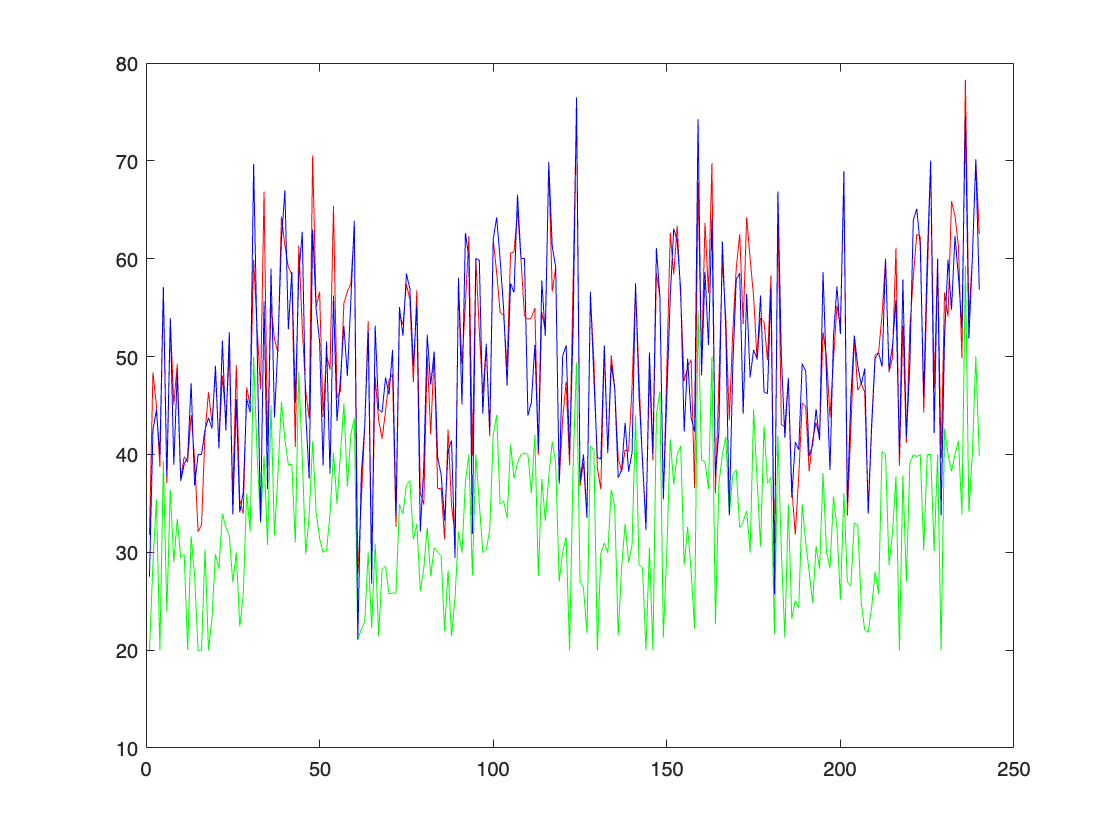

intances_comb_optimal=min(allMakespans);

figure
plot(intances_comb_optimal,'g')
hold on 
plot(SHH_means_means_means_byInstance,'r')
hold on 
plot(CHH_means_means_means_byInstance,'b')

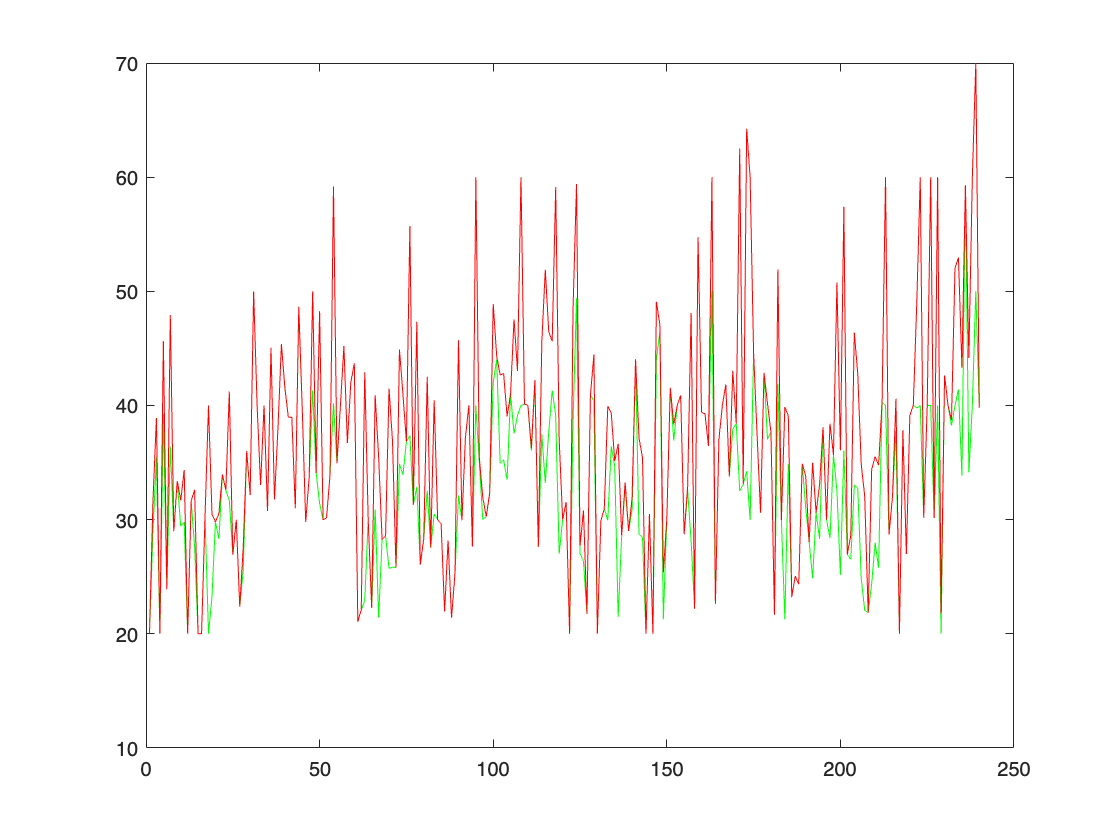

figure
plot(intances_comb_optimal,'g')
hold on 
plot(SHH_mins_mins_mins_byInstance,'b')
hold on 
plot(SHH_mins_mins_mins_byInstance,'r')

%Obtaining the RMSEs
SHH_means_RMSE=rmse(SHH_means_means_means_byInstance,intances_comb_optimal)

SHH_means_RMSE = 17.3590

CHH_means_RMSE=rmse(CHH_means_means_means_byInstance,intances_comb_optimal)

CHH_means_RMSE = 17.0411

SHH_mins_RMSE=rmse(SHH_mins_mins_mins_byInstance,intances_comb_optimal)

SHH_mins_RMSE = 7.9186

CHH_mins_RMSE=rmse(CHH_mins_mins_mins_byInstance,intances_comb_optimal)

CHH_mins_RMSE = 9.6554